# Lab6: **Analysis of accuracy decrease of filtration in conditions of correlated biased state and measurement noise**

Team1: Dmitry Shadrin and Eugenii Israelit, Skoltech

clc; clear; close all;
addpath('functions/');

n = 200;
x1 = 5;
v1 = 1;
t = 1;
sigmaA = 0.2;
sigmaN = 20;
bias = 0.2;
A = normrnd(0, sigmaA, 1, n)+bias;
Noise = normrnd(0, sigmaN, 1, n);

F = [1, t; 0, 1];
G = [(t^2)/2; t];
H = [1, 0];
P = [ 10000, 0;   0, 10000; ];

ErrSum = zeros(1,n);
M = 500;


***part I:***

***Divergence of Kalman filter when bias of acceleration (state noise) is neglected in assimilation algorithm. Development of optimal Kalman filter that takes into account bias of acceleration (state noise).***

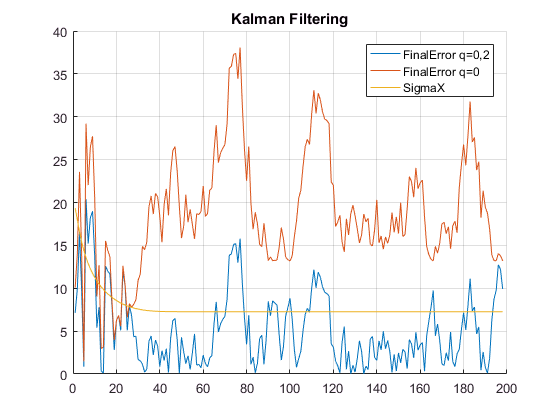



BiasCorrection = [bias, 0];
figure; hold on  
for i=1:length(BiasCorrection)
  
    for j=1:M
        [ X, Z ] = calcAccStateSpace( A, Noise, x1, v1, F, G, H );
        [ Xk, SigmaX ] = calcKalman(Z, sigmaA, sigmaN, x1, v1, F, G, H, P, BiasCorrection(i) );
        ErrCur = ( X(1,:) - Xk(1,:) ).^2;
        ErrSum = ErrSum + ErrCur;
    end
    FinalError = ( ErrSum(3:end)./(M-1) ).^0.5;
    plot(FinalError);

end

plot(SigmaX(3:end));
grid
legend('FinalError q=0,2','FinalError q=0','SigmaX');
title('Kalman Filtering');

***part II:***

**Sensitivity of estimation results obtained by a Kalman filter that doesn’t take into account correlation of state noise (acceleration) and measurement noise.**

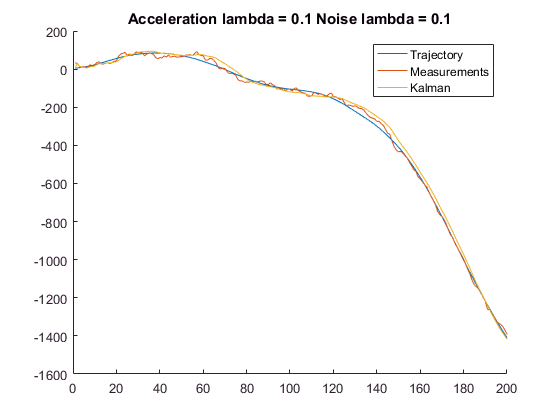

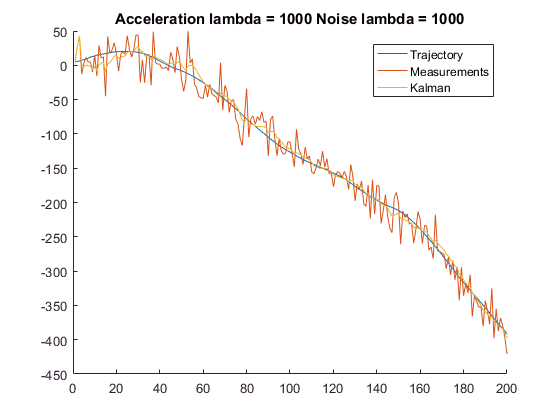

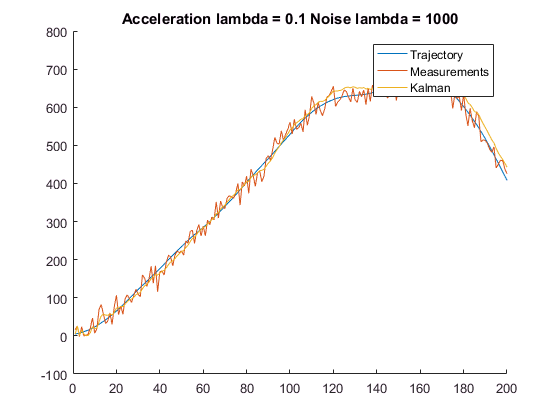

   
sigmaXi = 1;
Lambda = [ 0.1,  0.1;   1000, 1000;   0.1,  1000 ];

for i=1:length(Lambda)
    A = gaussMarkov( n, sigmaA, sigmaXi, Lambda(i,1), t );
    Noise = gaussMarkov( n, sigmaN, sigmaXi, Lambda(i,2), t );
    [ X, Z ] = calcTrajectory( A, Noise, x1, v1, t);
    
    for j=1:M
        [ Xk, SigmaX ] = calcKalman(Z, sigmaA, sigmaN, x1, v1, F, G, H, P, 0);
        ErrCur = ( X(1,:) - Xk(1,:) ).^2;
        ErrSum = ErrSum + ErrCur;
    end
    FinalError = ( ErrSum(3:end)./(M-1) ).^0.5;

    figure;
    hold on
    plot(X);
    plot(Z);
    plot(Xk(1,:));
    title(['Acceleration lambda = ', num2str(Lambda(i,1)), ' Noise lambda = ', num2str(Lambda(i,2)) ])
    legend('Trajectory', 'Measurements', 'Kalman');
end